## Load the Data and place into seperate containers

clear;
load exp2.mat 
time = exp2.X.Data;
vel_motor = exp2.Y(1).Data;
vel_table = exp2.Y(2).Data;
voltage = exp2.Y(3).Data;
%sim_voltage = timeseries(voltage, time);
%save 'sim_voltage' -v7.3 sim_voltage
%sim_velocity = timeseries(vel_table, time);
%save 'sim_velocity' -v7.3 sim_velocity

## Filter Data

% Filter parameter
%tau_lp = 1/(40*pi);
%G_f = 1/(tau_lp+1);
%vel_table = lowpass(vel_table, G_f);
%vel_motor = lowpass(vel_motor, G_f);

windowSize = 5; 
b = (1/windowSize)*ones(1,windowSize);
a = 1;
vel_table = filter(b,a,vel_table);
vel_motor = filter(b,a,vel_motor);

## Plot for visualization

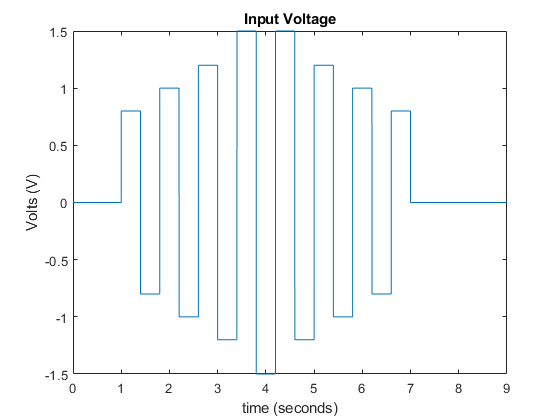

plot(time,voltage)
title('Input Voltage')
ylabel('Volts (V)')
xlabel('time (seconds)')

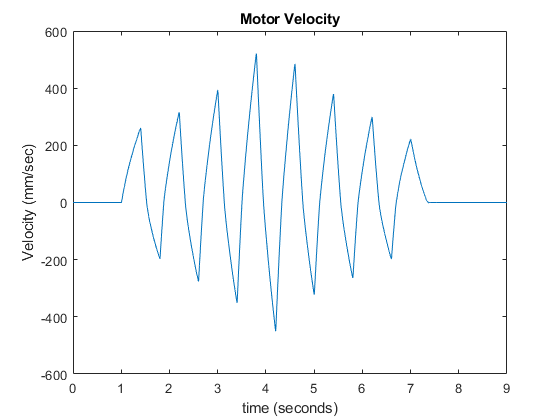


plot(time,vel_motor)
title('Motor Velocity')
ylabel('Velocity (mm/sec)')
xlabel('time (seconds)')

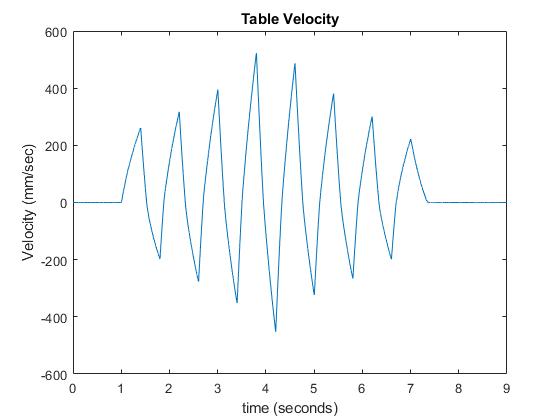


plot(time,vel_table)
title('Table Velocity')
ylabel('Velocity (mm/sec)')
xlabel('time (seconds)')

## Calculate Accelerations Numerically

acc_motor = diff(vel_motor);
time_acc = time(1:numel(acc_motor))

time_acc =          0    0.0010    0.0020    0.0030    0.0040    0.0050    0.0060    0.0070    0.0080    0.0090    0.0100    0.0110    0.0120    0.0130    0.0140    0.0150    0.0160    0.0170    0.0180    0.0190    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490


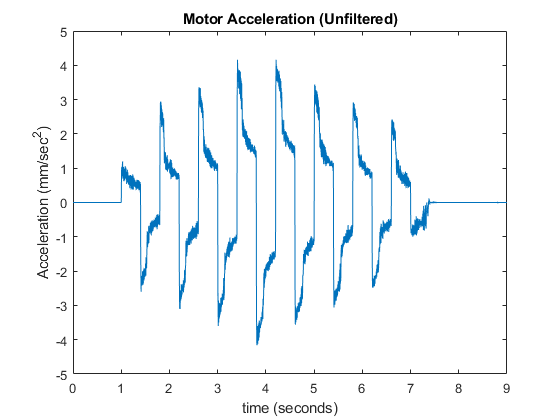

plot(time_acc,acc_motor)
title('Motor Acceleration (Unfiltered)')
ylabel('Acceleration (mm/sec^2)')
xlabel('time (seconds)')

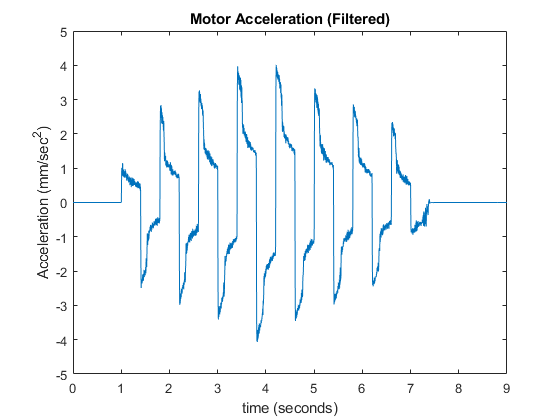


% Filter
%acc_filter = lowpass(acc_motor, G_f);
acc_filter = filter(b,a,acc_motor);
plot(time_acc,acc_filter)
title('Motor Acceleration (Filtered)')
ylabel('Acceleration (mm/sec^2)')
xlabel('time (seconds)')

## Find Parameters using Least Squares

X = zeros(numel(time_acc), 3);
X(:,1) = acc_filter;
X(1:1001,1) = 0; % Clean up the noise at the start
X(7400:end,1) = 0; % Clean up the noise at the start
X(:,2) = vel_motor(1:end-1);
X(1:1001,2) = 0; % Clean up the noise
X(7400:end,2) = 0; % Clean up the noise at the start
X(:,3) = sign(X(:,2));

Y = voltage(1:end-1)';

beta = mvregress(X,Y)

beta =     0.5537
    0.0007
    0.2789
